# Channel Matched Filter Equalizer

% Uplink
% Power V.S. Number of Antennas
% Linear and Rectangular Formation

## Global Parameter

clc;
clearvars;

Rtot = 10;
K = 10;
dn = 0.5;

M1 = [4, 8, 8, 16, 16];
M2 = [8, 8, 16, 16, 32];
M = M1 .* M2;
sample = 5;

time = 100;
suffix = 0;
taps = 4;

alpha = 0.0;
eta = 0;
mu = 0;


## Correlation Matrix

for index = 1 : sample
    for i = 1 : M(index)
        for j = 1 : M(index)
            dist(i, j) = abs(i - j) * dn;
        end
    end
    A = alpha .^ dist;
    exp_1d(index) = trace(A * A);
    clear A;
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    A = besseli(0, arg) ./ besseli(0, eta);
    bsl_1d(index) = trace(A * A');
    clear A dist;
    
    i = 1;
    for c1 = 1 : M1(index)
        for r1 = 1 : M2(index)
            j = 1;
            for c2 = 1 : M1(index)
                for r2 = 1 : M2(index)
                    dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                    j = j + 1;
                end
            end
            i = i + 1;
        end
    end
    dist = sqrt(dist .* dn);
    A = alpha .^ dist;
    exp_2d(index) = trace(A * A);
    clear A;
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    A = besseli(0, arg) ./ besseli(0, eta);
    bsl_2d(index) = trace(A * A');
    clear A;
end
clear dist;


## Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Mathematical Results

for l = 1 : taps
    for k = 1 : K
        V1(k, l) = d(l, k) ^ 2;
        V2(k, l) = d(l, k);
    end
end
first = sum(V1, 2);
second = sum(V2, 2);

for k = 1 : K
    Vg0 = (1 ./ (M .* K)) .* (M .* (first(k)) + (M .^ 2) .* (second(k)) ^ 2);
    Vn0 = (1 - V2(k) / K);
    
    Vg1 = (1 ./ (M .* K)) .* (exp_1d .* (first(k)) + (M .^ 2) .* (second(k)) ^ 2);
    Vn1 = (exp_1d ./ M) .* (1 - V2(k) / K);
        
    Vg2 = (1 ./ (M .* K)) .* (bsl_1d .* (first(k)) + (M .^ 2) .* (second(k)) ^ 2);
    Vn2 = (bsl_1d ./ M) * (1 - V2(k) / K);
        
    Vg3 = (1 ./ (M .* K)) .* (exp_2d .* (first(k)) + (M .^ 2) .* (second(k)) ^ 2);
    Vn3 = (exp_2d ./ M) .* (1 - V2(k) / K);
        
    Vg4 = (1 ./ (M .* K)) .* (bsl_2d .* (first(k)) + (M .^ 2) .* (second(k)) ^ 2);
    Vn4 = (bsl_2d ./ M(index)) .* (1 - V2(k) / K);
end

factor = (time) / (time + suffix);

r = (2 * Rtot) / (K * factor);

c_0 = (2 ^ r - 1) ./ (K * Vg0);

p_0 = (2 ^ r - 1) ./ (K * Vg0 - K * (2 ^ r - 1) * Vn0);
p_1 = (2 ^ r - 1) ./ (K * Vg1 - K * (2 ^ r - 1) * Vn1);
p_2 = (2 ^ r - 1) ./ (K * Vg2 - K * (2 ^ r - 1) * Vn2);
p_3 = (2 ^ r - 1) ./ (K * Vg3 - K * (2 ^ r - 1) * Vn3);
p_4 = (2 ^ r - 1) ./ (K * Vg4 - K * (2 ^ r - 1) * Vn4);

dbc = 10 * log10(c_0);

db0 = 10 * log10(p_0);
db1 = 10 * log10(p_1);
db2 = 10 * log10(p_2);
db3 = 10 * log10(p_3);
db4 = 10 * log10(p_4);


## Visualization

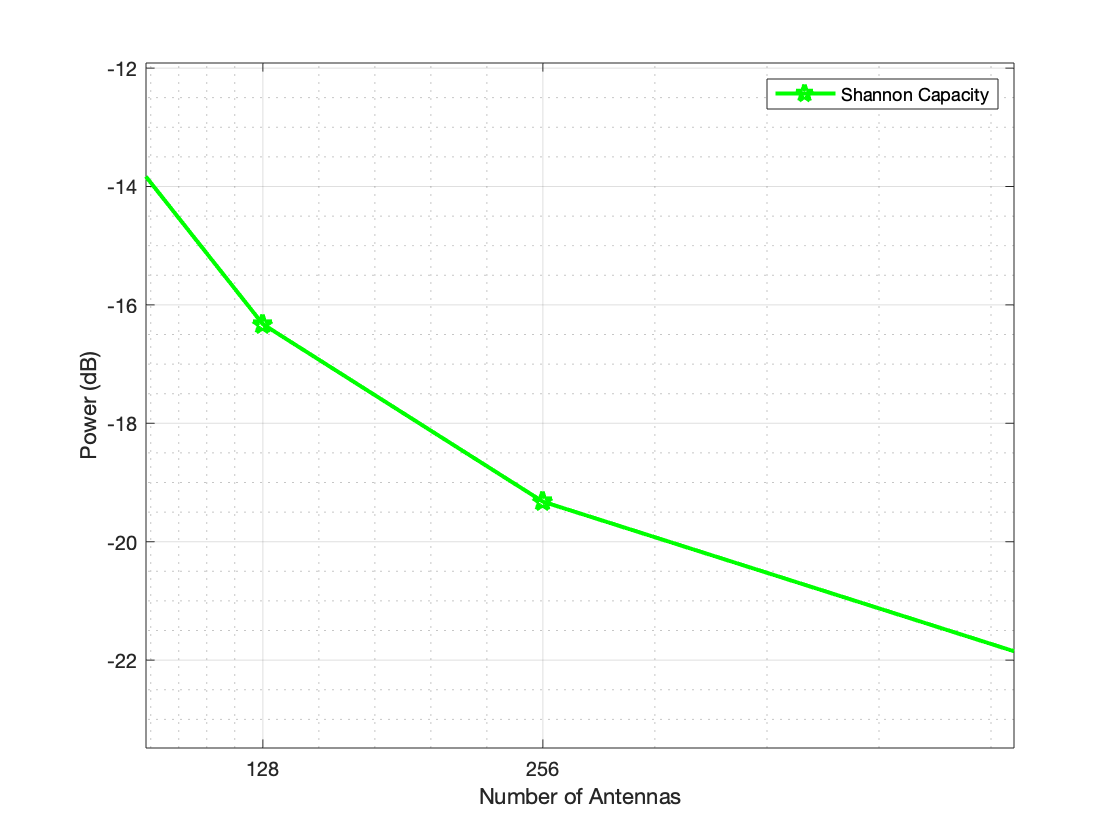

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_c = 'Shannon Capacity';
name_0 = 'Uncorrelated Channel';
name_1 = strcat('CMFP (1D), \alpha=', num2str(alpha));
name_2 = strcat('CMFP (1D), \eta=', num2str(eta), ', \mu=', angel);
name_3 = strcat('CMFP (2D), \alpha=', num2str(alpha));
name_4 = strcat('CMFP (2D), \eta=', num2str(eta), ', \mu=', angel);

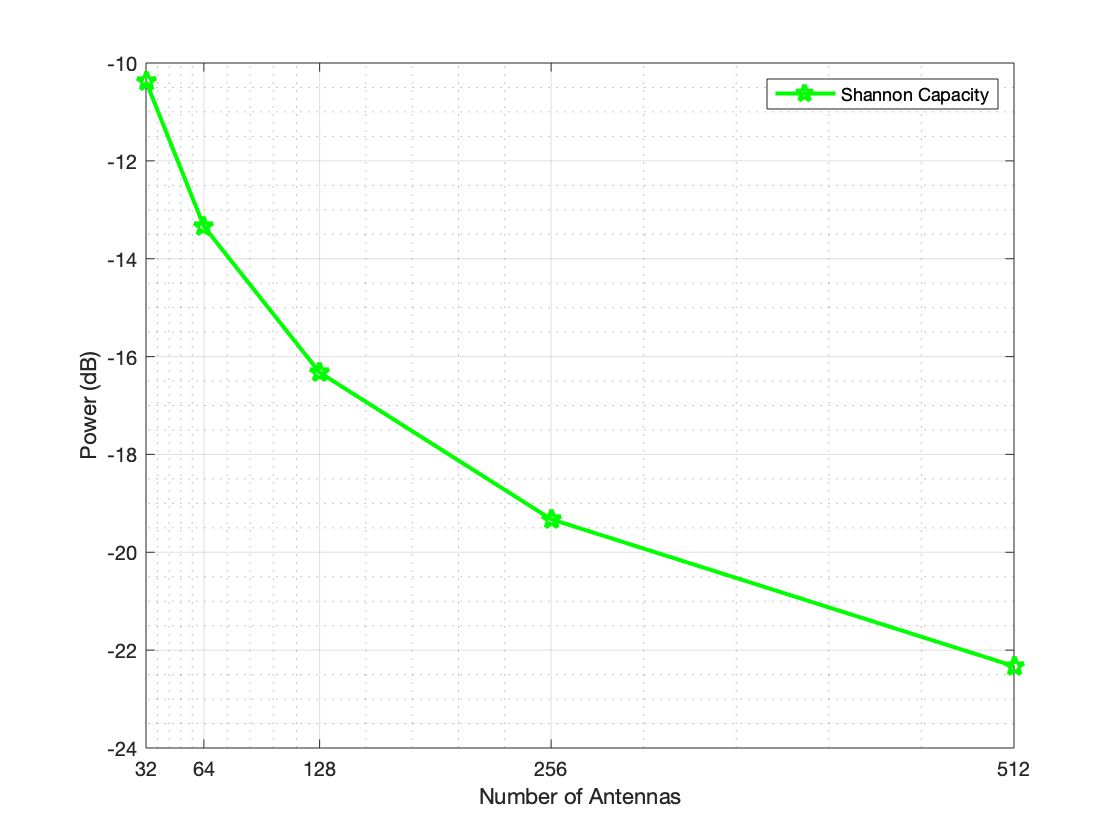



figure;
plot(M, dbc, '-gp', 'DisplayName', name_c, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10);
ylabel('Power (dB)', 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend();
grid on;
grid minor;

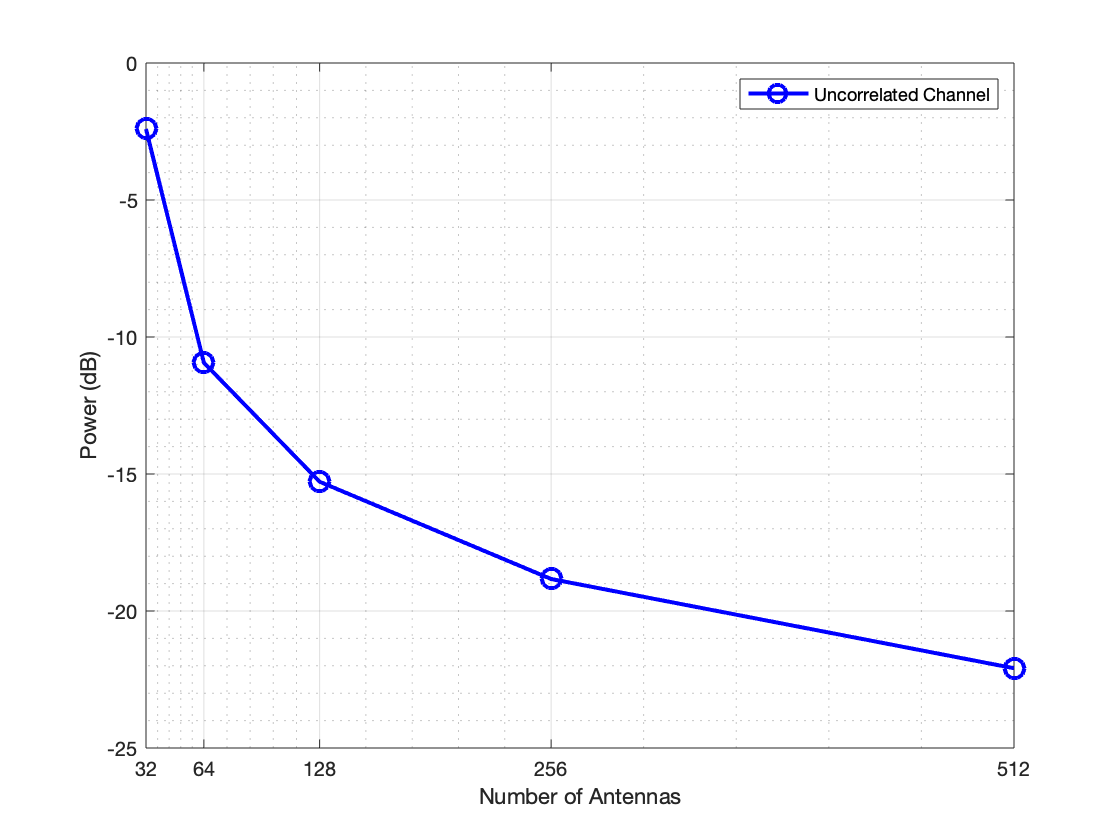



figure;
plot(M(1 : sample), db0(1 : sample), '-bo', 'DisplayName', name_0, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10);
ylabel('Power (dB)', 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend();
grid on;
grid minor;


%{
figure;
plot(M, db1, '-bo', 'DisplayName', name_1, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend()
grid on;
grid minor;


figure;
plot(M, db2, '-k*', 'DisplayName', name_2, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend()
grid on;
grid minor;


figure;
plot(M, db3, '--md', 'DisplayName', name_3, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend()
grid on;
grid minor;


figure;
plot(M, db4, '--rs', 'DisplayName', name_4, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend()
grid on;
grid minor;
%}
